## Saccades modeling

Say we have N saccads, each of them would require 4 parameters: 

-     x projection of initial speed;

-     y projection of initial speed;

-     initial accelleration modulus as relation to initial speed modulus.

We will generate them sequetially changing directions of the speed.

clear all;

predictableSeed = 1.5;
randomGenerator = rng(predictableSeed);

saccadesNumber = 4;
saccadesNumber = saccadesNumber * 4;

saccades_vx = (rand(saccadesNumber, 1) + 1) / 2;
saccades_vx = saccades_vx.*repmat([1 -1  1 -1], 1, floor(saccadesNumber / 4))';

saccades_vy = (rand(saccadesNumber, 1) + 1) / 2;
saccades_vy = saccades_vy.*repmat([1  1 -1 -1], 1, floor(saccadesNumber / 4))';

saccades_lambda = 1 - (rand(saccadesNumber, 1) + 1) / 10;

saccades = [saccades_vx saccades_vy saccades_lambda];

Each saccade could be generated using given random parameters and constants

saccadeConstants = [60 60 100];
saccadeConstants = repmat(saccadeConstants, saccadesNumber, 1);

saccades = array2table(saccades.*saccadeConstants, ...
    'VariableNames', {'vx', 'vy', 'lambda'})

saccades =       vx         vy       lambda
    _______    _______    ______

     42.511     42.519    80.421
     -51.61     46.761    84.668
     30.003    -34.212    83.081
     -39.07    -35.943    86.845
     34.403     54.022    83.135
     -32.77     59.048    81.654
     35.588    -39.403    89.817
    -40.367     -50.77    82.499
     41.903     56.292    80.111
    -46.165     56.838    82.518
     42.576    -32.551    87.196
    -50.557    -31.172    82.107
     36.134     35.095    88.968
    -56.344     56.344    85.521
     30.822     -32.95    80.914
    -50.114    -42.633    87.064



firstSaccade = saccades(1,:)

firstSaccade =       vx        vy      lambda
    ______    ______    ______

    42.511    42.519    80.421


Now let's simulate a time model for first saccade

% initialize everything with 1s instead of 0s?
% matlab :(

i = 1;
origin(i).x = 1;
origin(i).y = 1;

saccadicPeriod = 100;

while i < saccadicPeriod
    origin(i + 1).x = origin(i).x - firstSaccade.vx / firstSaccade.lambda * ...
        exp(-firstSaccade.lambda * (i - 1));
    origin(i + 1).y = origin(i).y - firstSaccade.vy / firstSaccade.lambda * ...
        exp(-firstSaccade.lambda * (i - 1));
    i = i + 1;
end;

figure

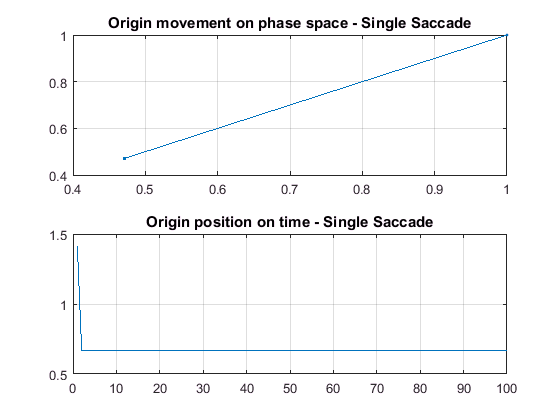

sp1 = subplot(2,1,1);
plot([origin.x], [origin.y], '.-');
title('Origin movement on phase space - Single Saccade');
grid(sp1,'on');

sp2 = subplot(2,1,2);
plot(1:size(origin,2), sqrt([origin.x].^2 + [origin.y].^2));
title('Origin position on time - Single Saccade');
grid(sp2,'on');

well, that's hardly impressive. Let's get all of them:

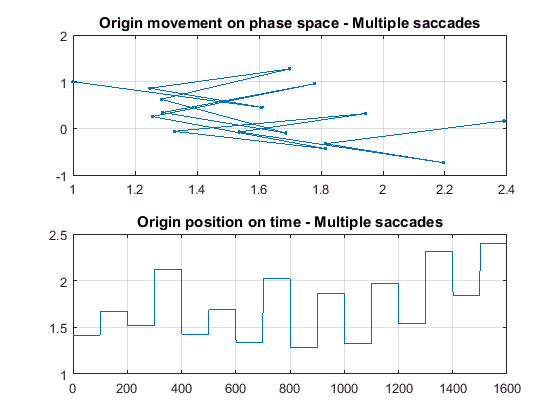

i = 1;
timeFromStart = 0;
clear('origin');
origin(1).x = 1;
origin(1).y = 1;

for j = 1:saccadesNumber
    saccade = saccades(j,:);

    while i < saccadicPeriod + timeFromStart
        origin(i + 1).x = origin(i).x - saccade.vx / saccade.lambda ...
            * exp(-saccade.lambda * (i - timeFromStart));
        origin(i + 1).y = origin(i).y - saccade.vy / saccade.lambda * ...
            exp(-saccade.lambda * (i - timeFromStart));
        i = i + 1;
    end;
    timeFromStart = saccadicPeriod + timeFromStart;
    clear('saccade');
end;

figure;
sp1 = subplot(2,1,1);
plot([origin.x], [origin.y], '.-');
title('Origin movement on phase space - Multiple saccades');
grid(sp1,'on');

sp2 = subplot(2,1,2);
plot(1:(timeFromStart), sqrt([origin.x].^2 + [origin.y].^2));
title('Origin position on time - Multiple saccades');
grid(sp2,'on')

Apply those to the checkerboard

p = 5;
rows = 8;
n = rows * p;
m = rows * p;
I = checkerboard(p, rows);

ori = origin(1:n*m);

Undefined function 'origin' for input arguments of type 'double'.


cc = [ori.x; ori.y]';
cc = cc.*(-1);
D = reshape(cc, n, m, 2);

out = imwarp(I, D);
imshow(imresize([I out], 3));